## declare your working path

cd("/Users/alvissss/Documents/MATLAB/EC4305 Computation Session/")

## importing data

clear
clc

new_prices= readmatrix("full_agg_data.csv")

new_prices = 1.0e+05 *

       NaN    4.6865    0.0001    0.0000
       NaN    4.6733    0.0001    0.0000
       NaN    4.7056    0.0001    0.0000
       NaN    4.7497    0.0001    0.0000
       NaN    4.7713    0.0001    0.0000
       NaN    4.7436    0.0001    0.0000
       NaN    4.7243    0.0001    0.0000
       NaN    4.6590    0.0001    0.0000
       NaN    4.6853    0.0001    0.0000
       NaN    4.6213    0.0001    0.0000
       NaN    4.5824    0.0001    0.0000
       NaN    4.6129    0.0001    0.0000
       NaN    4.4791    0.0001    0.0000
       NaN    4.5223    0.0001    0.0000
       NaN    4.4598    0.0001    0.0000


X=new_prices(:,4);  % X= inflation
Y=new_prices(:,3); % Y= lg resale prices

% get summary statistics of X
mean(X)

ans = 0.0175

std(X)

ans = 0.0215

% get summary statistics of Y
mean(Y)

ans = 5.5473

std(Y)

ans = 0.0587

## nonparametric estimation

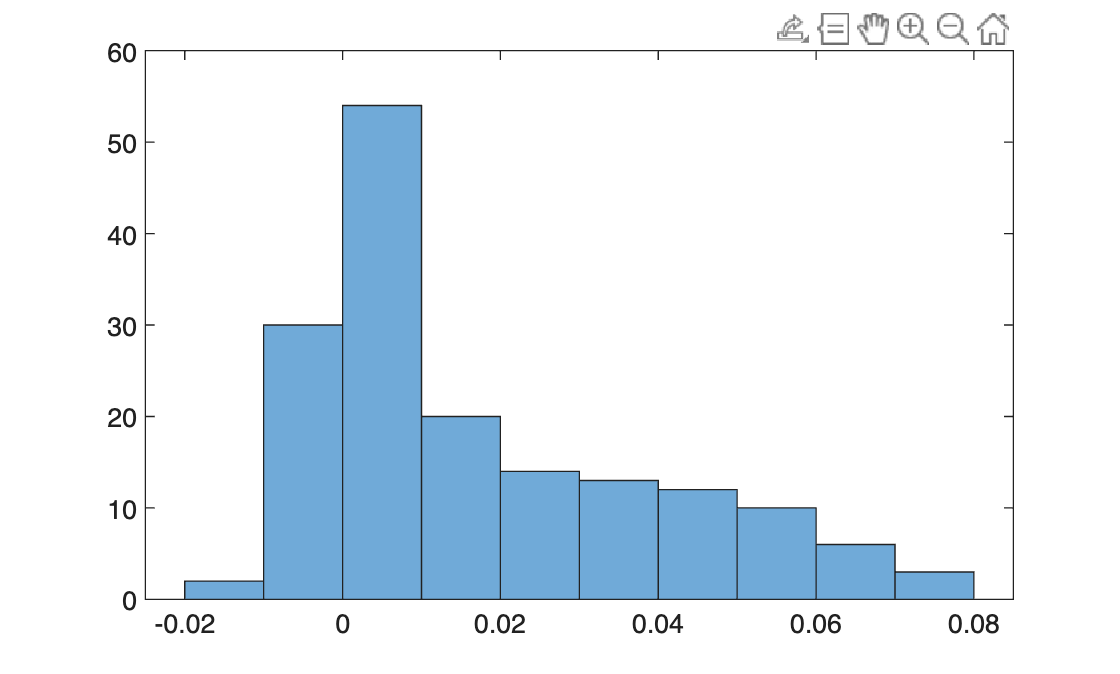

% plotting histogram of X and Y
histogram(X)

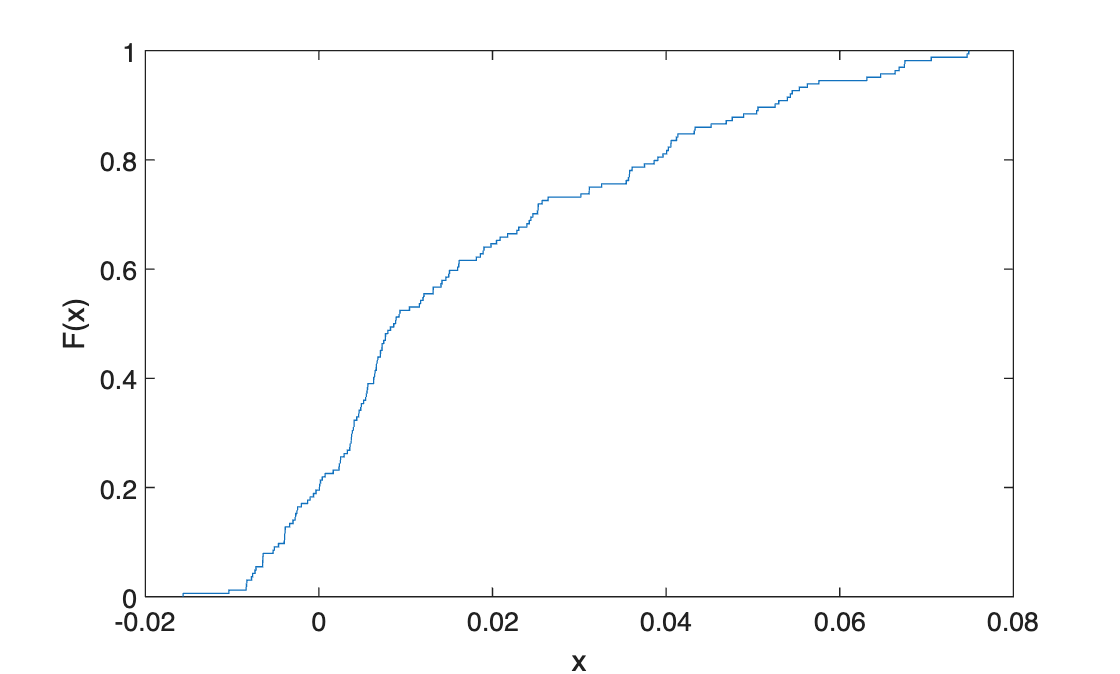

histogram(Y)

% plotting the empirical cdf of X and Y
ecdf(X)

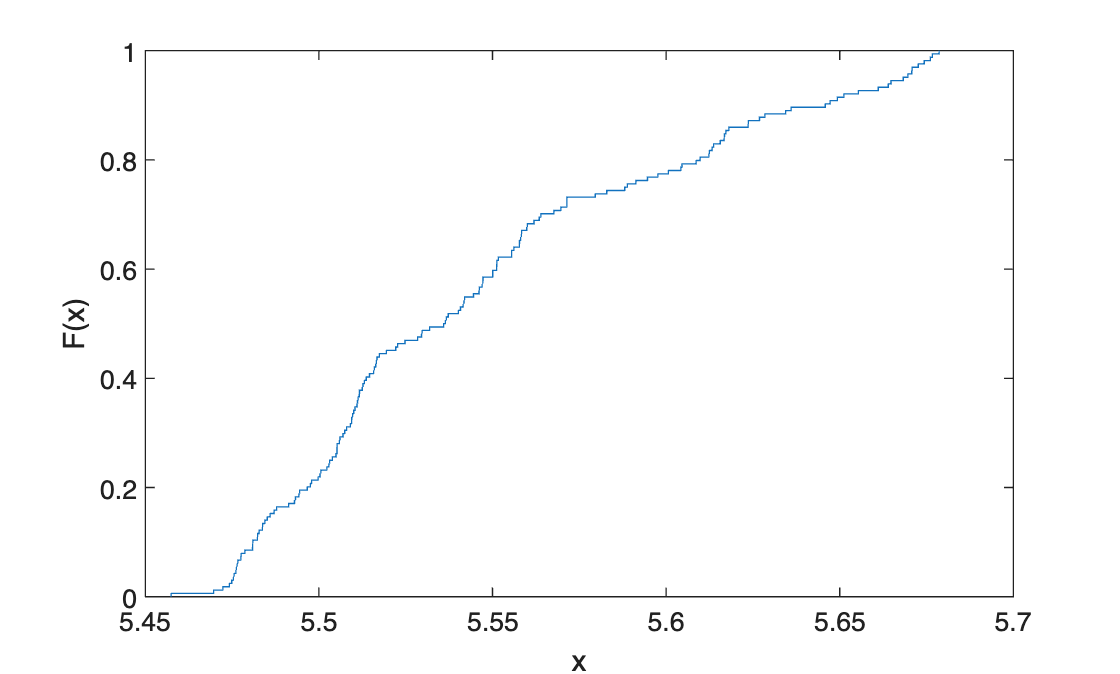

ecdf(Y)

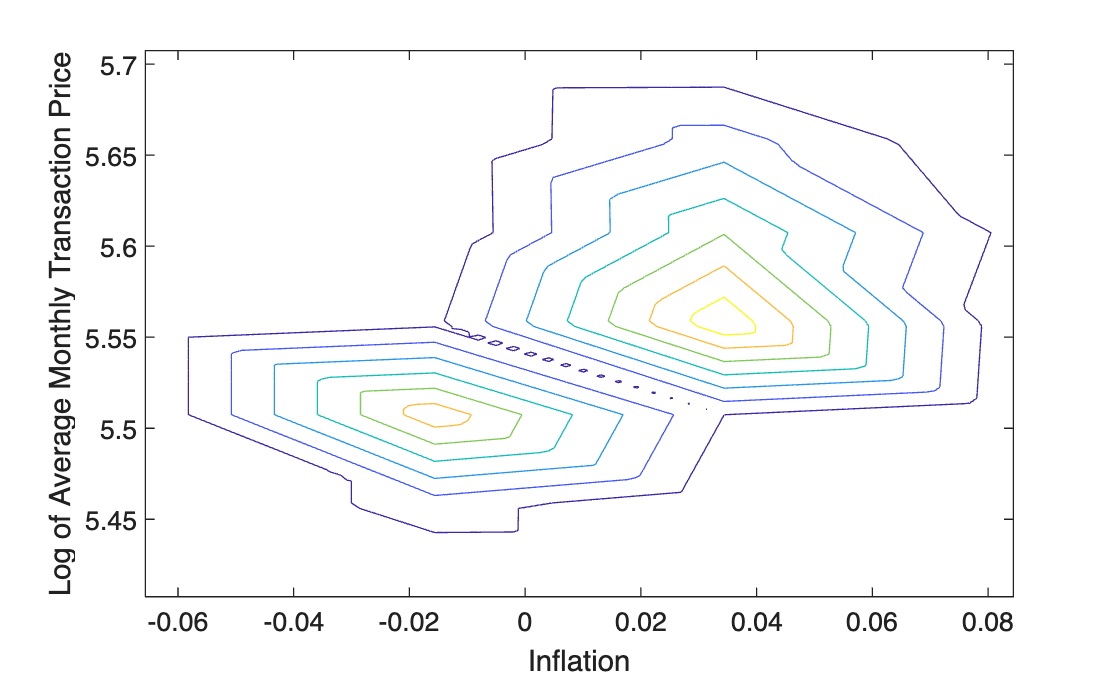

[Fx,X_unique]=ecdf(X);   % X_unique indicates the sorted unique value of vector X and F is the CDF of corresponding value of X_unique
[Fy,Y_unique]=ecdf(Y);   % do the same for Y_unique

% estimate bivariate joint density function at customized value
X_min= min(X);
Y_min= min(Y);
X_max= max(X);
Y_max= max(Y);
gridx = (X_min-0.05):.05:(X_max+0.05);
gridy = (Y_min-0.05):.05:(Y_max+0.05);
[x,y] = meshgrid(gridx, gridy);
x = x(:); % this linearlize the matrix to a m*n dimension vector
y = y(:);
xi = [x y];
data= [X Y];
f_biv=ksdensity(data,xi);
ksdensity(data,xi,'PlotFcn','contour') % 3-D density graph
xlabel('Inflation')
ylabel('Log of Average Monthly Transaction Price')

## integral transformed data

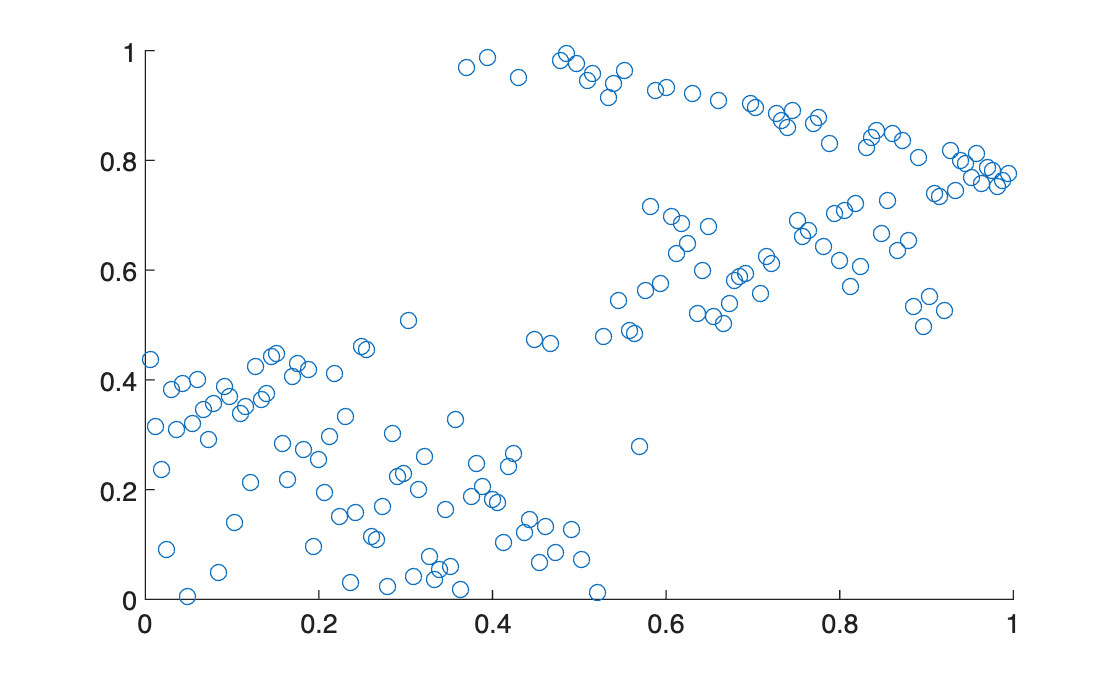

XX=[X Y]';
U=zeros(2,164);
for i=1:2
    for j=1:164
        U(i,j)=(1/(164+1))*sum(XX(i,:)<=XX(i,j));    % integral transform
    end
end

conD= U';

scatter(conD(:,1),conD(:,2));   % plot of integrated data

## coupla analysis

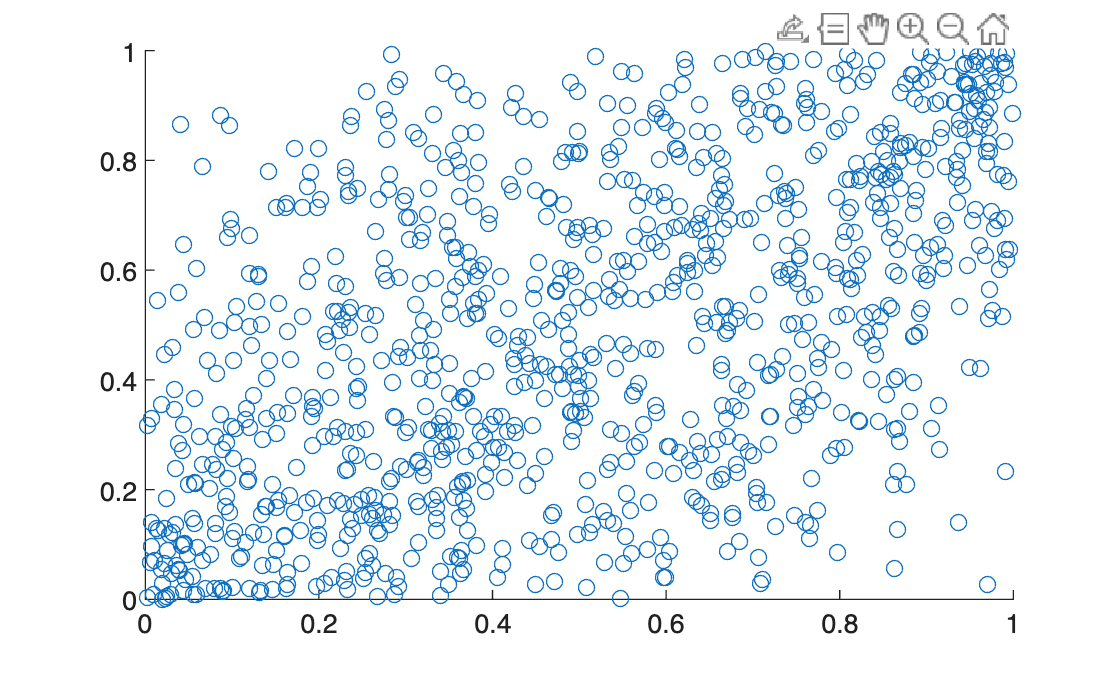

% fit the coupla to data
% we use a modified function of copulafit to derive the BIC and LL values for the families studied
[rhohat_gaussian,LL1] = copulafit_myown('gaussian',conD); 
[estimates, LL2] = copulafit_myown('t',conD); 
[thetaClayton, LL3] = copulafit_myown('Clayton',conD);
LL=[LL1 LL2 LL3]';
N= size(X,1)*ones(3,1);
K= [1;2;1];
BIC= 2*LL+(K.*log(N));
[minval,modelindex]= min(BIC); % it seems Gaussian copula best fits our data

u_sim = copularnd('gaussian',rhohat_gaussian,1000);
scatter(u_sim(:,1),u_sim(:,2));

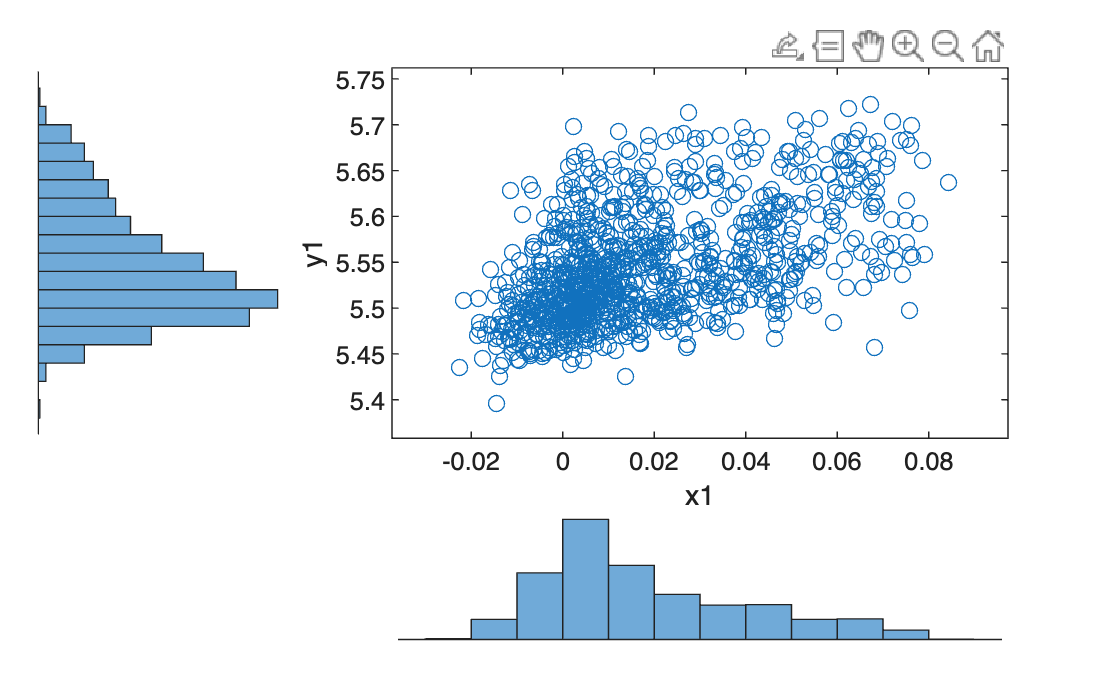

% take the fitted coupla back to data
% ksdensity(X,YI,..,'function','icdf') calculates the inverse CDF of values in X and evaluates it at probability values given in YI
x1 = ksdensity(X,u_sim(:,1),'function','icdf'); 
y1 = ksdensity(Y,u_sim(:,2),'function','icdf');

figure;
scatterhist(x1,y1)